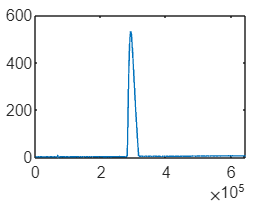

% Variables 

% Importing data into an array 
data = readmatrix("astra2_full_testdata.txt");
time = data(:,1);
pressure = data(:,2);
refpressure = 101728.25;
maxthrustaltitude = 220;

for i = 1:length(time) 
    time = data(:,1);
    pressure = data(:,2);

    if altitude(i)

    % Turning the pressure readings into altitude. 
    altitude = 44330 * (1-(pressure/refpressure).^(1/5.255));

    
    % Defining the initial time. 
    initEntryTime = time(find(altitude>0,1));
    
    maxThrustTime = time(find(altitude > maxthrustaltitude,1));
    initRecordTime = maxThrustTime - initEntryTime;
    

    









% Functions. 
